Initiate

close all
clearvars

clf
clc
if ~exist('../Figures', 'dir')
    mkdir('../Figures')
end
cd ../results

Load data files

load('dxyz.dat',             '-ascii');
load('Nxyz.dat',             '-ascii');
load('InitPoint.dat',        '-ascii');
rho.data = load('rhoAmb.dat',           '-ascii');
Links.ID = load('EstablishedLinks.dat', '-ascii');
gnd.alt  = load('z_gnd.dat',            '-ascii');

Derive main parameters

Links.Nb = size(Links.ID);
Links.Nb = Links.Nb(1);
N.x = Nxyz(1);
N.y = Nxyz(2);
N.z = Nxyz(3);

d.x = dxyz(1);           % _m
d.y = dxyz(2);           % _m
d.z = dxyz(3);           % _m

L.x = (N.x-1)*d.x;         % _m
L.y = (N.y-1)*d.y;         % _m
L.z = (N.z-1)*d.z;         % _m

S.x = InitPoint(1);   % _m
S.y = InitPoint(2);   % _m
S.z = InitPoint(3);   % _m
S.R = InitPoint(4);   % _m

S.i = round(S.x/d.x);
S.j = round(S.y/d.y);
S.k = round(S.z/d.z);

rho.data = ConvertTo3d(rho.data,Nxyz); % _C/_m^3

clear Nxyz
clear dxyz
clear InitPoint
if isunix
    cd ../viz
else
    cd ..\viz
end

% Linear spaces for the three position dimensions:
x = ((0:(N.x-1))*d.x)*1e-3;
y = ((0:(N.y-1))*d.y)*1e-3;
z = ((0:(N.z-1))*d.z + gnd.alt)*1e-3;

[X,Y,Z]=ndgrid(x,y,z);
rho.max = .95* max(max(max(rho.data)));
rho.min = .95* min(min(min(rho.data)));

Map ColorScale

gnd.color = [.75 .75 .75];%[.718 .255 .055];
color     = colormap(jet(Links.Nb));
is.BW = 1;%input('Is plot Monochrome? (1: yes, else: no)\n>> ');
if (is.BW == 1)
    for ii=1:Links.Nb
        color(ii,:) = [0 0 1];
    end
end

Set movie recording

is.Rec = 1; % input('Record the movie? (1: yes, else: no)\n>> ');
if (is.Rec == 1)
    if isunix
        Movie = VideoWriter('../Figures/lightning','MPEG-4');
    else
        Movie = VideoWriter('..\Figures\lightning','MPEG-4');
    end
    open(Movie);
end

Draw the tree

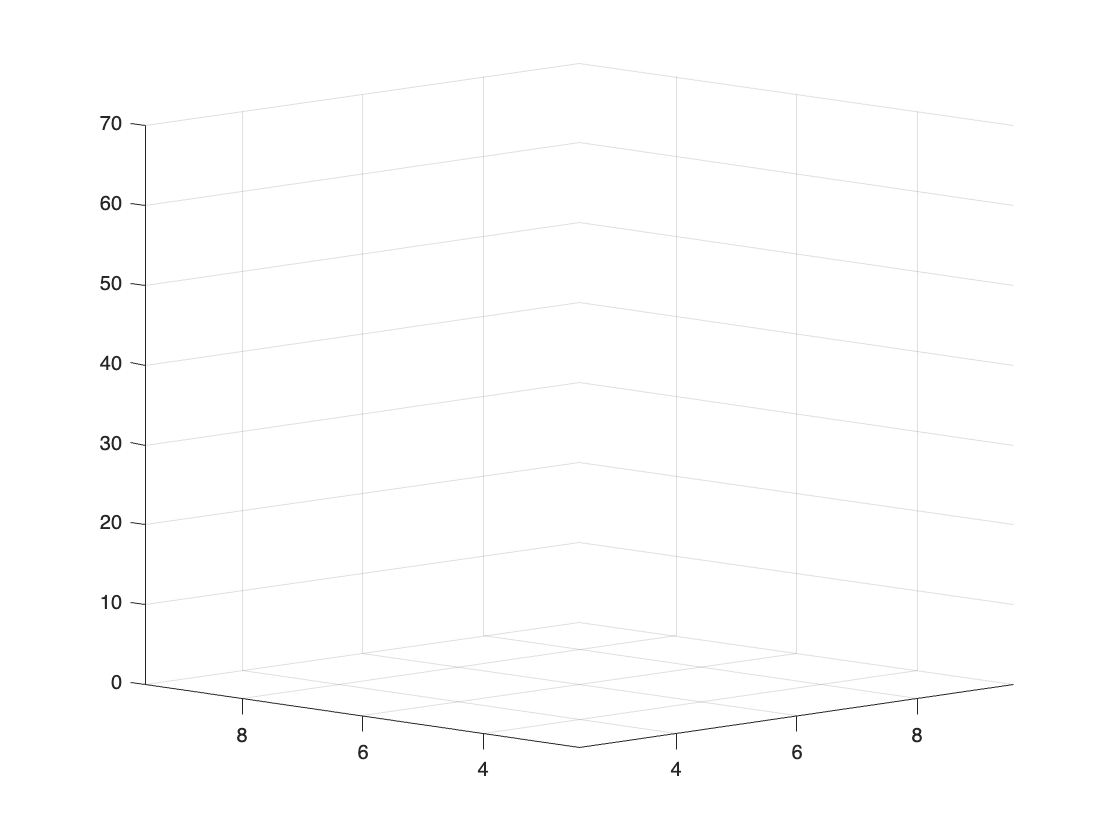

Error using interp3 (line 148)
Input grid is not a valid MESHGRID.

Error in isonormals (line 79)
        n(:,1)=interp3(x, y, z, nx, verts(:,1), verts(:,2), verts(:,3));

Error in plottingChargeR

figure(1);

set(gcf,'Units','inches','OuterPosition', [20 20 20 20]/3,'Color','white');
hold on;
grid on;

% Sets bounds for the axes (comment out if clouds get cut off):
axis([L.x*1/5 L.x*4/5 L.y*1/5 L.y*4/5 gnd.alt 2/2*(L.z+gnd.alt)]*1e-3) % Slight crop
%axis([0 L.x 0 L.y gnd.alt 2/2*(L.z+gnd.alt)]*1e-3)                     % Full span 

% Plots the cloud structure with the defined function below:
plottingChargeRegions('white',0.5,rho,X,Y,Z);


% Represents the neutrally charged (grounded) surface:
P.x = [L.x 0 0 L.x]*1e-3;
P.y = [L.y L.y 0 0]*1e-3;
P.z = [gnd.alt gnd.alt gnd.alt gnd.alt]*1e-3;
patch(P.x, P.y, P.z, gnd.alt,'FaceColor',gnd.color,'DisplayName','Ground');

% For-loop to plot lightning discharge links:
for ii=1:Links.Nb
    %     if(rem(ii,10)==0)
    %         %         pause;
    %     end
    
    plot3(...
        [Links.ID(ii,1)*d.x      , Links.ID(ii,4)*d.x      ]*1e-3,...
        [Links.ID(ii,2)*d.y      , Links.ID(ii,5)*d.y      ]*1e-3,...
        [Links.ID(ii,3)*d.z+gnd.alt, Links.ID(ii,6)*d.z+gnd.alt]*1e-3,...
        'Color',color(ii,:),'HandleVisibility','off');
    %     axis equal
    box on
    title(['Lightning discharge after ', int2str(ii) ,' step(s)'],'FontSize',12,'FontWeight','bold');
    set(gca,'FontSize',10);
    view([33 10])
    frame = getframe(gcf);
    if(is.Rec == 1)
        writeVideo(Movie,frame);
    end
end

%camlight; lighting gouraud


frame = getframe(gcf);
hold off;

Record the movie

if (is.Rec == 1)
    writeVideo(Movie,frame);
    close(Movie);
end